clear;clc;close all
load('orbitdeterm_finalproj_KFdata.mat')

## Define Constants

mu = 3.986004418e5; %398800; % [km^3/s^2] Gravitational Constant
r0 = 6678; % [km] nominal orbit radius
w0 = sqrt(mu/r0^3);
% Constants for the output vector
Re = 6378; % [km]
we = 2*pi/86400; % [rad/s]
N = 12; % Number of ground stationss^2
dt = 10; % [s]
dtf = 0.1; % [s] fine dt
Tf = 14000; % [s] Final time (one orbit)
G = [0 0;1 0;0 0;0 1]; % Big omega matrix
O = dt*G;


## Nominal Trajectory

t = 0:dt:Tf;
t_fine = 0:dtf:Tf;
opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
xnom(:,1) = [r0;0;0;r0*w0];
for kk = 1:length(t)-1
   f = @(t,x) nLEQ(t,x);
   [~,xnom_ODE] = ode45(f,[0 10],xnom(:,kk),opts);
   xnom(:,kk+1) = xnom_ODE(end,:)';
end

# MONTE CARLO SIMULATION

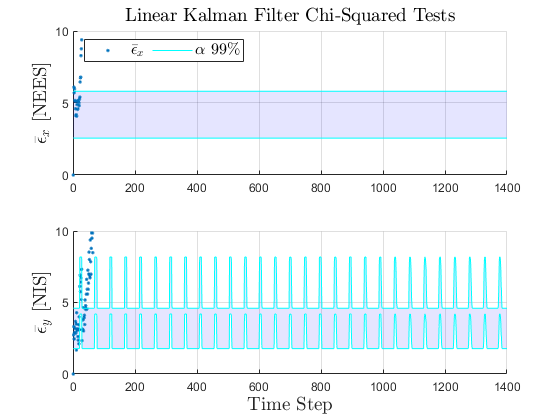

nMC = 20; % Number of monte carlo runs
dx(:,1) = [0; 0; 0; 0]; % State estimate
P(:,:,1) = eye(4)*1e-10;
opts = odeset('RelTol',1e-12,'AbsTol',1e-12);
for mm = 1:nMC
    % Get the Truth ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    
    xNL(:,1) = mvnrnd([r0;0;0;r0*w0],P(:,:,1))';
    for kk = 1:length(t)-1
       w = mvnrnd(zeros(1,2),Qtrue)';
       f_stoch = @(t,x) nLEQ(t,x) + G*w;
       [~,xNL_ODE] = ode45(f_stoch,[0 10],xNL(:,kk),opts);
       xNL(:,kk+1) = xNL_ODE(end,:)';
    end

    % Get the Outputs ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    visSatsNL = diag(1:12)*ones(N,size(t,2));
    for kk = 1:length(t)
        
        for nn = 1:12
            thi = wrapToPi((nn - 1)*pi/6); % Theta 0 for ground station i
            Xis = Re*cos(we*t(kk)+thi);
            Yis = Re*sin(we*t(kk)+thi);
            dXis = -Re*we*sin(we*t(kk)+thi);
            dYis = Re*we*cos(we*t(kk)+thi);
            x_stat(:,kk,nn) = [Xis;dXis;Yis;dYis];
    
            thLim = we*t(kk)+thi;
            v = mvnrnd(zeros(1,3),Rtrue)';
            yNL(:,kk,nn) = [sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2);
                        ((xNL(1,kk)-Xis)*(xNL(2,kk)-dXis)+(xNL(3,kk)-Yis)*(xNL(4,kk)-dYis))/(sqrt((xNL(1,kk)-Xis)^2+(xNL(3,kk)-Yis)^2));
                        atan2((xNL(3,kk)-Yis),(xNL(1,kk)-Xis))];
            
            ynom(:,kk,nn) = [sqrt((xnom(1,kk)-Xis)^2+(xnom(3,kk)-Yis)^2);
                    ((xnom(1,kk)-Xis)*(xnom(2,kk)-dXis)+(xnom(3,kk)-Yis)*(xnom(4,kk)-dYis))/(sqrt((xnom(1,kk)-Xis)^2+(xnom(3,kk)-Yis)^2));
                    atan2((xnom(3,kk)-Yis),(xnom(1,kk)-Xis))];

            yNL_noisy(:,kk,nn) = yNL(:,kk,nn) + v;
    
            inView = and(angdiff(yNL(3,kk,nn),thLim) <= pi/2,angdiff(yNL(3,kk,nn),thLim) >= -pi/2);
            if ~inView
                yNL_noisy(:,kk,nn) = [NaN;NaN;NaN];
                yNL(:,kk,nn) = [NaN;NaN;NaN];
                visSatsNL(nn,kk) = NaN;
            end
        end
    end
    
    % Run the KF ~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~~
    
    Qassumed = [0.9 0.3;0.3 0.9];
    Qassumed = Qtrue;
    Rassumed = Rtrue;
    Qt_diag = diag(Qassumed);
    visSatsBool = ~isnan(visSatsNL);
    numSats(mm,:) = sum(visSatsBool);
    dx(:,1) = [0; 0; 0; 0];
    dx_predict(:,1) = [0; 0.075; 0; -0.021]*0; % State prediction
    NEES(1) = 0;
    NIS(1) = 0;
    P_predict(:,:,1) = eye(4);
    for kk = 1:length(t)-1
        % Define matrices
        F = eye(4) + dt*A(xnom(:,kk),mu);
        satNums = visSatsNL(visSatsBool(:,kk+1),kk+1);
        H_kp1 = [];
        dy_kp1 = [];
        for ii = 1:numSats(mm,kk+1)
            H_kp1 = [H_kp1; C(xnom(:,kk+1),t(kk+1),satNums(ii))];
            
            yMeasurement = yNL_noisy(:,kk+1,satNums(ii));
            yMeasurement(3) = wrapToPi(yMeasurement(3));
            
            yNominal = ynom(:,kk+1,satNums(ii));
            yNominal(3) = wrapToPi(yNominal(3));
            
    
            dynew = yMeasurement - yNominal;
            dynew(3) = wrapToPi(dynew(3));
    
    
            dy_kp1 = [dy_kp1 ; dynew];
        end
        Rused = kron(eye(numSats(mm,kk+1)),Rassumed);
            % Prediction Step
            dx_predict(:,kk+1) = F*dx(:,1);
            P_predict(:,:,kk+1) = F*P(:,:,kk)*F' + O*Qassumed*O';
    
    
            if ~isempty(H_kp1)
            % Measurement Update
                K = P_predict(:,:,kk+1)*H_kp1'*inv(H_kp1*P_predict(:,:,kk+1)*H_kp1'+Rused);
                dx(:,kk+1) = dx_predict(:,kk+1) + K*(dy_kp1-H_kp1*dx_predict(:,kk+1));
                P(:,:,kk+1) = (eye(4) - K*H_kp1)*P_predict(:,:,kk+1);
            else
            % Just use prediction if no ground staions in view
                dx(:,kk+1) = dx_predict(:,kk+1);
                P(:,:,kk+1) = P_predict(:,:,kk+1);
            end
            e_dx(:,kk+1) = xNL(:,kk+1) - dx(:,kk+1) - xnom(:,kk+1);
            if ~isempty(dy_kp1)
                e_dy = dy_kp1-H_kp1*dx_predict(:,kk+1);
                if length(e_dy) == 3
                    e_dy(3) = wrapToPi(e_dy(3));
                elseif length(e_dy) == 6
                    e_dy(3) = wrapToPi(e_dy(3));
                    e_dy(6) = wrapToPi(e_dy(6));
                end
                NIS(kk+1) = e_dy'*inv(H_kp1*P_predict(:,:,kk+1)*H_kp1'+Rused)*e_dy;
            else
                e_dy = 0;
                NIS(kk+1) = 0;
            end
            NEES(kk+1) = e_dx(:,kk+1)'*inv(P(:,:,kk+1))*e_dx(:,kk+1);
            
    end
    MC_out.NIS(mm,:) = NIS;
    MC_out.NEES(mm,:) = NEES;
end

a = 0.01;onesVec = ones(length(t),1);


Chi.NEES.r1 = onesVec*chi2inv(a/2,nMC*4)/nMC;
Chi.NEES.r2 = onesVec*chi2inv(1-a/2,nMC*4)/nMC;
Chi.NEES.vals = mean(MC_out.NEES,1);


for kk = 1:length(t)
    nMC_y(kk) = nMC - sum(numSats(kk) == 0);
    p_y(kk) = mean(numSats(~(numSats(:,kk) == 0),kk))*3;
end

Chi.NIS.r1 = (chi2inv(a/2,nMC_y.*p_y)/nMC)';
Chi.NIS.r2 = (chi2inv(1-a/2,nMC_y.*p_y)/nMC)';
% Chi.NIS.r1(find(Chi.NIS.r1 == 0)) = Chi.NIS.r1(1);
% Chi.NIS.r2(find(Chi.NIS.r2 == 0)) = Chi.NIS.r2(1);
Chi.NIS.vals = mean(MC_out.NIS,1);

figure
subplot(2,1,1)
patch([t/dt fliplr(t/dt)], [Chi.NEES.r1' fliplr(Chi.NEES.r2')], 'blue','FaceAlpha',.1,'LineStyle','none')
hold on
plot(Chi.NEES.vals,'.')
plot(Chi.NEES.r1,'c')
plot(Chi.NEES.r2,'c')
title('Linear Kalman Filter Chi-Squared Tests','Interpreter','Latex','FontSize',14)
ylabel('$\bar{\epsilon}_x$ [NEES]','Interpreter','Latex','FontSize',14)
legend('','$\bar{\epsilon}_x$','$\alpha$ 99\%','Interpreter','Latex','FontSize',12,'Location','NorthWest','Orientation','horizontal')
ylim([0 10])
grid on
xlim([0 Tf/dt])

subplot(2,1,2)
patch([t/dt fliplr(t/dt)], [Chi.NIS.r1' fliplr(Chi.NIS.r2')], 'blue','FaceAlpha',.1,'LineStyle','none')
hold on
plot(Chi.NIS.vals,'.')
plot(Chi.NIS.r1,'c')
plot(Chi.NIS.r2,'c')
ylabel('$\bar{\epsilon}_y$ [NIS]','Interpreter','Latex','FontSize',14)
xlabel('Time Step','Interpreter','Latex','FontSize',14)
grid on
ylim([0 10])
xlim([0 Tf/dt])
saveas(gca,'LKFChiSquare.png')

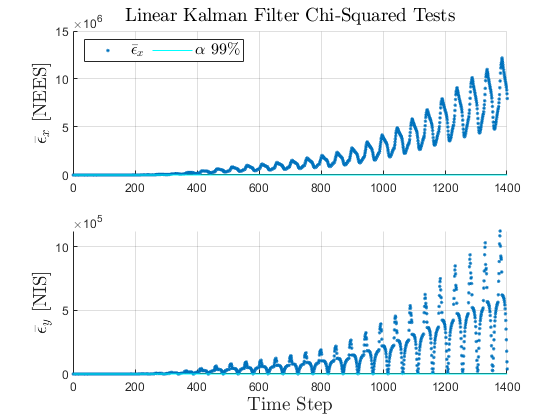



figure
subplot(2,1,1)
patch([t/dt fliplr(t/dt)], [Chi.NEES.r1' fliplr(Chi.NEES.r2')], 'blue','FaceAlpha',.1,'LineStyle','none')
hold on
plot(Chi.NEES.vals,'.')
plot(Chi.NEES.r1,'c')
plot(Chi.NEES.r2,'c')
title('Linear Kalman Filter Chi-Squared Tests','Interpreter','Latex','FontSize',14)
ylabel('$\bar{\epsilon}_x$ [NEES]','Interpreter','Latex','FontSize',14)
legend('','$\bar{\epsilon}_x$','$\alpha$ 95\%','Interpreter','Latex','FontSize',12,'Location','NorthWest','Orientation','horizontal')
grid on
xlim([0 Tf/dt])

subplot(2,1,2)
patch([t/dt fliplr(t/dt)], [Chi.NIS.r1' fliplr(Chi.NIS.r2')], 'blue','FaceAlpha',.1,'LineStyle','none')
hold on
plot(Chi.NIS.vals,'.')
plot(Chi.NIS.r1,'c')
plot(Chi.NIS.r2,'c')
ylabel('$\bar{\epsilon}_y$ [NIS]','Interpreter','Latex','FontSize',14)
xlabel('Time Step','Interpreter','Latex','FontSize',14)
grid on
xlim([0 Tf/dt])
saveas(gca,'LKFChiSquareNoLim.png')

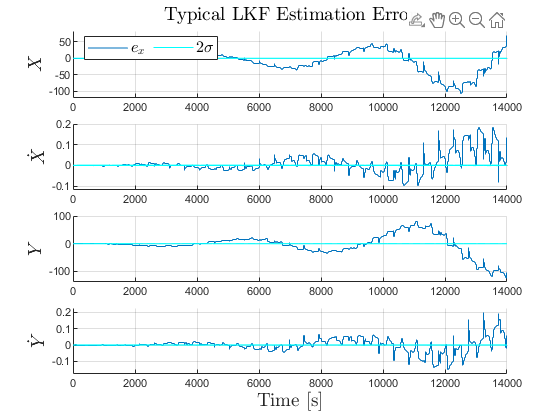


figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
% yLims = [100; 2; 100; 2];
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    patch([t fliplr(t)], [2*sqrt(squeeze(P(kk,kk,:))') fliplr(-2*sqrt(squeeze(P(kk,kk,:))'))], 'blue','FaceAlpha',.1)
    hold on
    stairs(t,e_dx(kk,:))
    plot(t,2*sqrt(squeeze(P(kk,kk,:))'),'c')
    plot(t,-2*sqrt(squeeze(P(kk,kk,:))'),'c')
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
%     ylim([-yLims(kk) yLims(kk)])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Typical LKF Estimation Error','Interpreter','Latex','FontSize',14)
legend('','$e_x$','$2\sigma$','Interpreter','Latex','FontSize',12,'Location','NorthWest','Orientation','horizontal')
saveas(gca,'LKFTypErr.png')

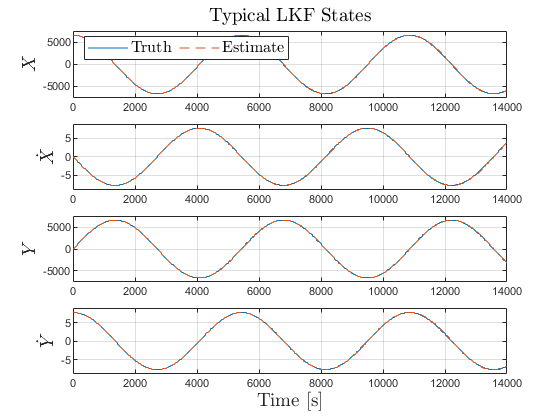



figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,xNL(kk,:))
    hold on
    stairs(t,xnom(kk,:)+dx(kk,:),'--')
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Typical LKF States','Interpreter','Latex','FontSize',14)
legend('Truth','Estimate','Interpreter','Latex','FontSize',12,'Location','NorthWest','Orientation','horizontal')
saveas(gca,'LKFTypStates.png')

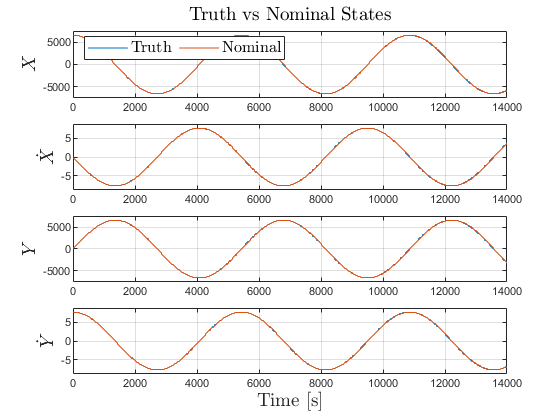




figure
ylabs = {'$X$','$\dot{X}$','$Y$','$\dot{Y}$'};
for kk = 1:4
    sb(kk) = subplot(4,1,kk);
    stairs(t,xNL(kk,:))
    hold on
    stairs(t,xnom(kk,:))
    grid on
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    axis padded
    xlim([0 Tf])
end
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
linkaxes(sb,'x')
subplot(4,1,1)
title('Truth vs Nominal States','Interpreter','Latex','FontSize',14)
legend('Truth','Nominal','Interpreter','Latex','FontSize',12,'Location','NorthWest','Orientation','horizontal')
saveas(gca,'LKFTruevNom.png')

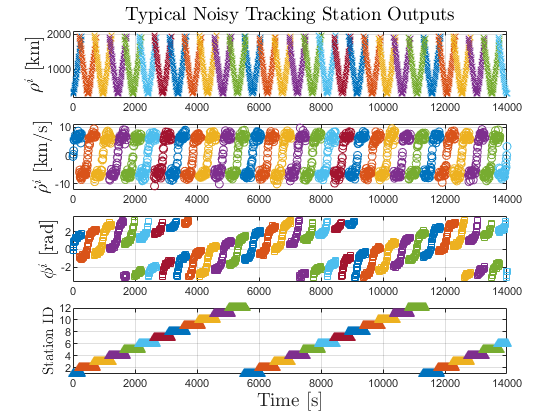



linType = {'x','o','square','^'};
ylabs = {'$\rho^i$ [km]','$\dot{\rho}^i$ [km/s]','$\phi^i$ [rad]','Station ID'};
figure
for kk = 1:3
    sb(kk) = subplot(4,1,kk);
    for nn = 1:12
        plot(t,yNL_noisy(kk,:,nn),linType{kk})
        hold on
    end
    ylabel(ylabs{kk},'Interpreter','Latex','FontSize',14)
    grid on
    hold off
    axis padded
    xlim([0 Tf])
end
sb(4) = subplot(4,1,4);
plot(t,visSatsNL,linType{4})
ylim([1 12])
grid on
ylabel(ylabs{4},'Interpreter','Latex','FontSize',11)
linkaxes(sb,'x')
xlabel('Time [s]','Interpreter','Latex','FontSize',14)
subplot(4,1,1)
title('Typical Noisy Tracking Station Outputs','Interpreter','Latex','FontSize',14)
saveas(gca,'LKFNoisyOut.png')